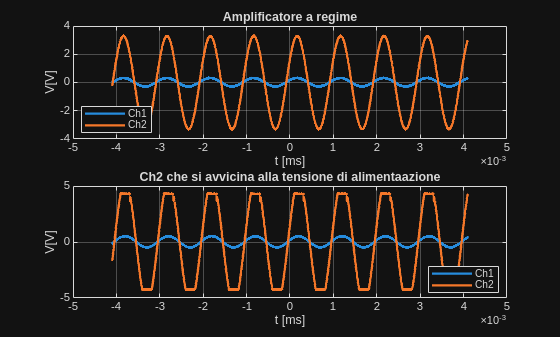

cd(fileparts(matlab.desktop.editor.getActiveFilename));

tbl1 = readtable("dati/acquisizione05.txt", NumHeaderLines=3);
tbl1.Properties.VariableNames = ["t", "Ch1", "Ch2"];

% --- Funzione modello ---

G
% --- Subplot 1: modulo ---
subplot(2,1,1)
plot(tbl1.t, tbl1.Ch1, 'LineWidth', 1.8)
hold on
plot(tbl1.t, tbl1.Ch2, 'LineWidth', 1.8)
hold off
xlabel('t [ms]')
ylabel('V[V]')
legend("Ch1", "Ch2", 'Location', 'best')
title('Amplificatore a regime')
grid on


% --- Esporta la figura ---
exportgraphics(gcf, "BestFit.pdf", ContentType = "vector");